# Анализ сигнала ЭКГ во временной области

Данный скрипт использует ядро **MATLAB **и** Signal Processing Toolbox**

Анализ QRS-комплекса позволяет оценить состояние сердечно-сосудистой системы пациента. Важно определить положение Q-, R- и S-зубцов в зашумлённых и данных ЭКГ. Для этого необходимо отфильтровать сигнал, убрать постоянную составляющую и обнаружить пики - локальные минимумы и максимумы.

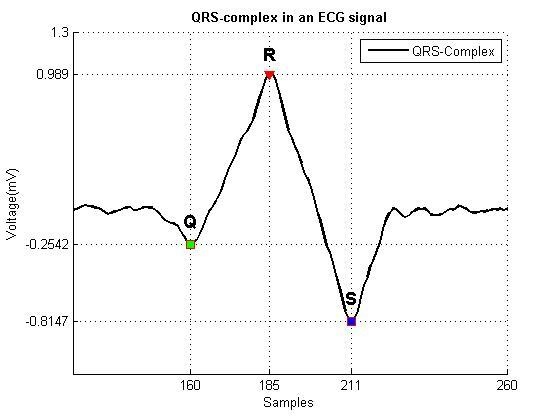

Загрузим и визуализируем данные ЭКГ из mat-файла.

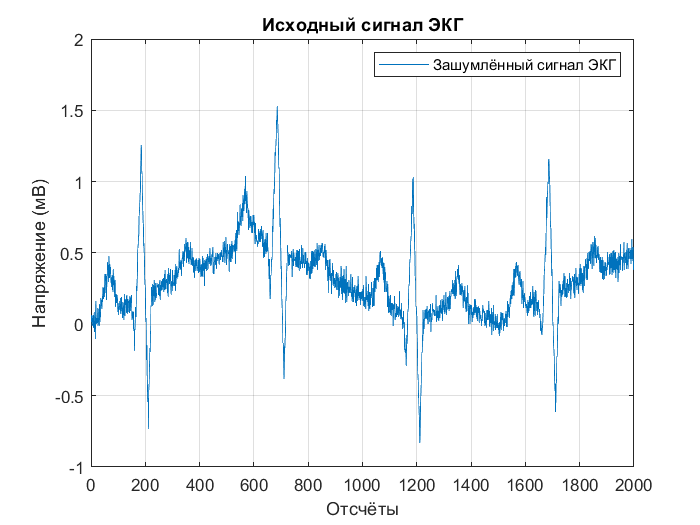

load noisyecg.mat
t = 1:length(noisyECG_withTrend);

plot(t,noisyECG_withTrend);
title('Исходный сигнал ЭКГ');
xlabel('Отсчёты');
ylabel('Напряжение (мВ)');
legend('Зашумлённый сигнал ЭКГ');
grid;

**Сглаживание сигнала**

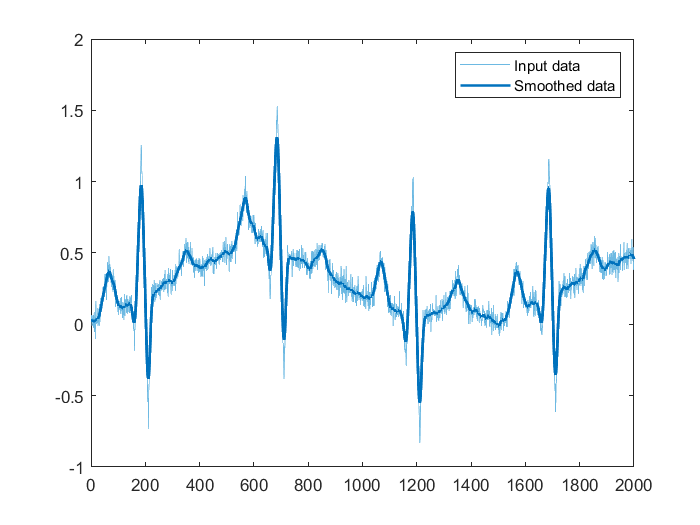

% Smooth input data
smoothedData = smoothdata(noisyECG_withTrend,'gaussian','SmoothingFactor',0.2);

% Display results
clf
plot(noisyECG_withTrend,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

**Выделение постоянной составляющей:**

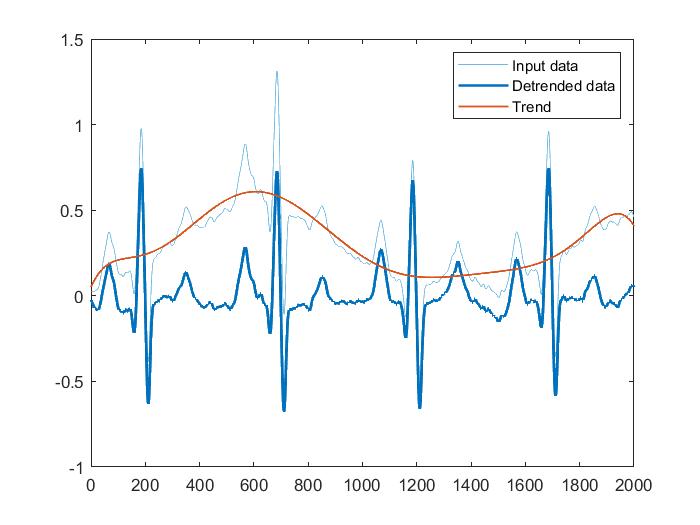

% Remove trend from data
detrendedData = detrend(smoothedData,8);

% Display results
clf
plot(smoothedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(smoothedData-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

**Нахождение локальных экстремумов:**

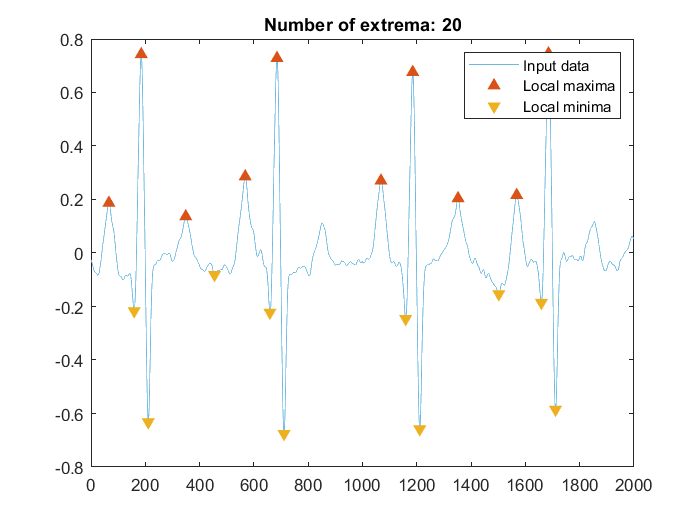

% Find local maxima and minima
maxIndices = islocalmax(detrendedData,'MaxNumExtrema',10);
minIndices = islocalmin(detrendedData,'MaxNumExtrema',10);

% Display results
clf
plot(detrendedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxIndices),detrendedData(maxIndices),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')

% Plot local minima
plot(find(minIndices),detrendedData(minIndices),'v','Color',[237 177 32]/255,...
    'MarkerFaceColor',[237 177 32]/255,'DisplayName','Local minima')
title(['Number of extrema: ' num2str(nnz(maxIndices)+nnz(minIndices))])
hold off
legend

**Анализ "программным" методом:**

Используем функцию **movmean** для операции скользящего среднего. Меняем размер окна для выделения постоянной составляющей - тренда:

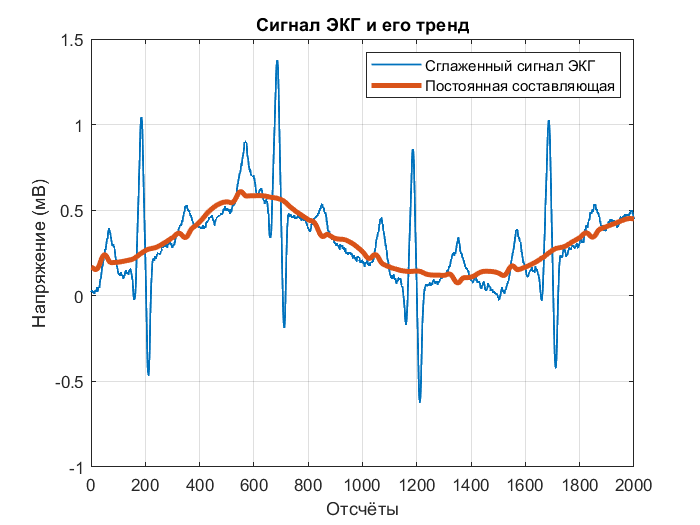

ECG_withTrend = movmean(noisyECG_withTrend,10);
plot(ECG_withTrend,'LineWidth',1); grid; hold on;
title('Сигнал ЭКГ и его тренд');
xlabel('Отсчёты');
ylabel('Напряжение (мВ)');

% размер окна - 300 отсчётов
mmean = movmean(ECG_withTrend,300);
plot(mmean,'LineWidth',3); hold off;
legend({'Сглаженный сигнал ЭКГ','Постоянная составляющая'});


ECG_data = ECG_withTrend - mmean;        % Удаление тренда

Находим зубцы Q, R и S при помощи функции **findpeaks **из** Signal Processing Toolbox:**

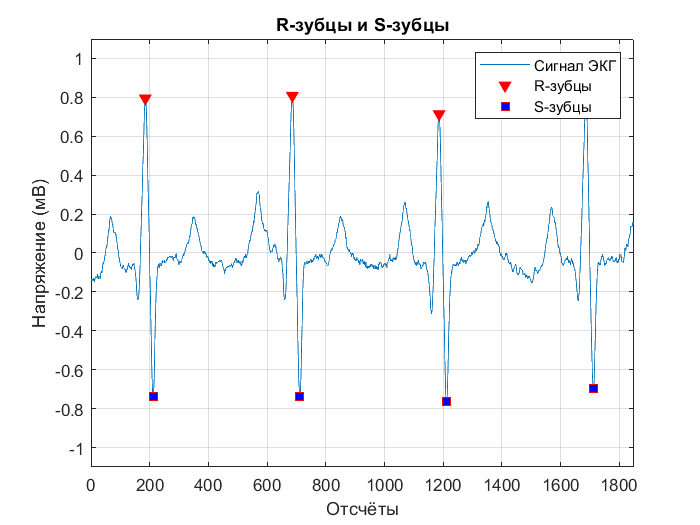

[~,locs_Rwave] = findpeaks(ECG_data,'MinPeakHeight',0.5,...
                                    'MinPeakDistance',200);
                                
[~,locs_Swave] = findpeaks(-ECG_data,'MinPeakHeight',0.5,...
                                        'MinPeakDistance',200);
plot(t,ECG_data); grid; hold on;
plot(locs_Rwave,ECG_data(locs_Rwave),'rv','MarkerFaceColor','r');
plot(locs_Swave,ECG_data(locs_Swave),'rs','MarkerFaceColor','b');
axis([0 1850 -1.1 1.1]);
legend('Сигнал ЭКГ','R-зубцы','S-зубцы');
xlabel('Отсчёты');
ylabel('Напряжение (мВ)');
title('R-зубцы и S-зубцы');
hold off;

Для нахождения Q-зубцов используем логическую индексацию:

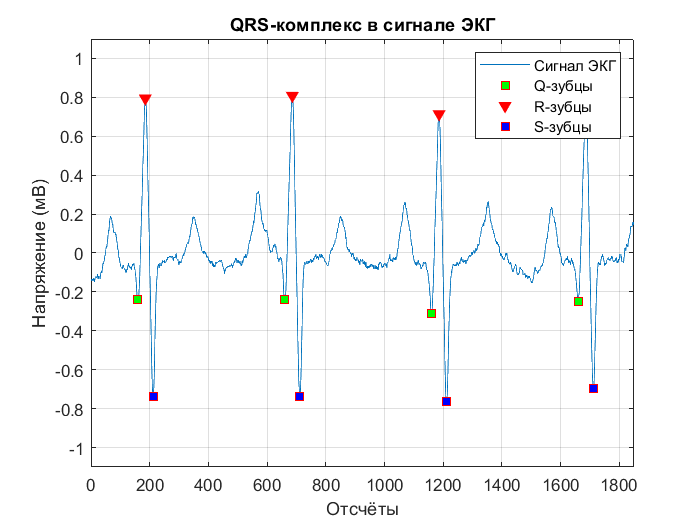

[~,min_locs] = findpeaks(-ECG_data,'MinPeakDistance',40);

% Пики значением от -0.2 мВ до -0.5 мВ
locs_Qwave = min_locs(ECG_data(min_locs)>-0.5 & ECG_data(min_locs)<-0.2);

plot(t,ECG_data); hold on;
plot(locs_Qwave,ECG_data(locs_Qwave),'rs','MarkerFaceColor','g');
plot(locs_Rwave,ECG_data(locs_Rwave),'rv','MarkerFaceColor','r');
plot(locs_Swave,ECG_data(locs_Swave),'rs','MarkerFaceColor','b');
grid;
title('QRS-комплекс в сигнале ЭКГ');
xlabel('Отсчёты');
ylabel('Напряжение (мВ)');
ax = axis;
axis([0 1850 -1.1 1.1]);
legend('Сигнал ЭКГ','Q-зубцы','R-зубцы','S-зубцы');